x = [0 0.5 1 1.5 2 2.5];
y = [0 1 0.8 1.8 1.6 2.4];
xspace = linspace(0,2.5,1000);
yspace = spline(x,y,xspace);

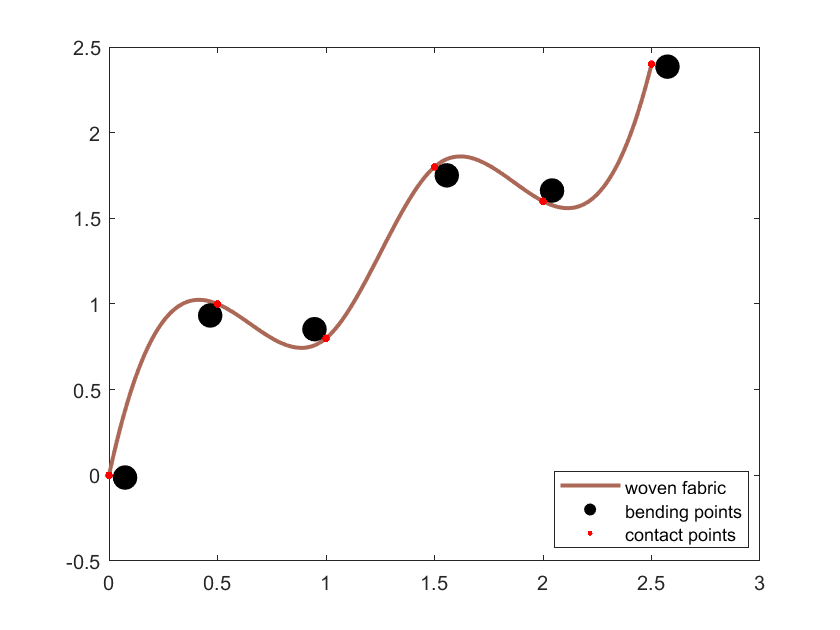

%% plot brown spline
plot(xspace, yspace, linewidth = 2, color = [171/255 104/255 87/255])
hold on
%% plot weaving points
% move the turning points by 0.5 markersize normal to the curve
slope = interp1(xspace,yspace,x) - interp1(xspace,yspace,x-0.01);
slope(1) = interp1(xspace,yspace,x(1)) + interp1(xspace,yspace,x(1)+0.01);
slope = slope ./ 0.01;
normalx = ones(size(slope));
normaly = -1./slope;
% flipping direction at points 2 and 3
normalx(2:3) = normalx(2:3)*-1;
normaly(2:3) = normaly(2:3)*-1;
% sizing
normalx = normalx./sqrt(1+normaly.^2);
normaly = normaly./sqrt(1+normaly.^2);
markersize = 0.15; % approximately
xplot = x + normalx * markersize / 2;
yplot = y + normaly * markersize / 2;
scatter(xplot,yplot,markersize*1000,'k','filled');
%% plot actual contact points
scatter(x,y, 100, '.r')
legend("woven fabric","bending points","contact points",location="best")